**Obiekt statyczny**

Poniżej przedstawiam dane, które zostały dodane do obszaru roboczego. Zmienne są zgodne z tymi, które zostały podane w treści zadania. Poniżej pisze także kod który wyświetli nam wykresy dla podstawowych paramterów zadanych w ilinstrukcji.

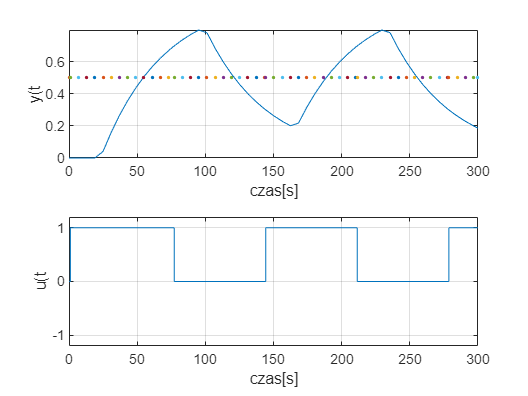

SP = 0.5;
tau = 22;
T = 45;
h = 0.05;

y = out.y;
u = out.u;

subplot(2,1,1)
plot(y.time,y.signals.values,y.time,SP,'.')
grid
xlabel('czas[s]')
ylabel('y(t')
subplot(2,1,2)
plot(u.time,u.signals.values)
grid
xlabel('czas[s]')
ylabel('u(t')
axis([0,300,-1.2,1.2])

Analiza wpływu szerokości histerezy regulatora h.

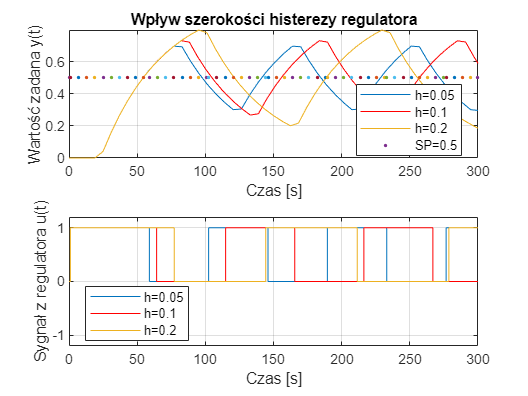

SP = 0.5;
tau = 22;
T = 45;
h = 0.05;

y = out.y;
u = out.u;

out1 = sim('sim_link.slx');
y1 = out1.y;
u1 = out1.u;
h = 0.1;

out2 = sim('sim_link.slx');
y2 = out2.y;
u2 = out2.u;
h = 0.2;

out3 = sim('sim_link.slx');
y3 = out3.y;
u3 = out3.u;

figure
subplot(2,1,1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, '.')
title("Wpływ szerokości histerezy regulatora")
legend("h=0.05", "h=0.1", "h=0.2", "SP=0.5", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")

subplot(2,1,2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("h=0.05", "h=0.1", "h=0.2", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Sygnał z regulatora u(t)")
axis([0,300,-1.2,1.2])

h = 0.05;

Analiza wpływu wartości opóźnienia obiektu tau:

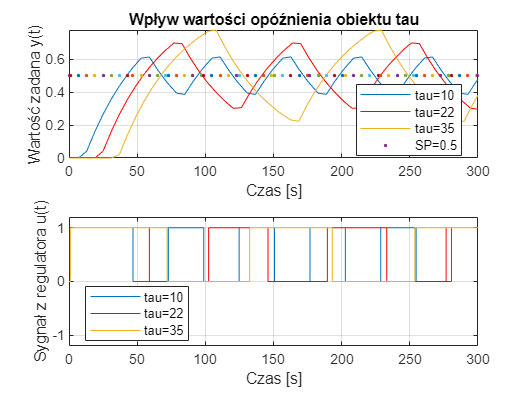

tau = 10;
out1 = sim('sim_link.slx');
y1 = out1.y;
u1 = out1.u;

tau = 22;
out2 = sim('sim_link.slx');
y2 = out2.y;
u2 = out2.u;

tau = 35;
out3 = sim('sim_link.slx');
y3 = out3.y;
u3 = out3.u;

figure
subplot(2,1,1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, '.')
title("Wpływ wartości opóźnienia obiektu tau")
legend("tau=10", "tau=22", "tau=35", "SP=0.5", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")

subplot(2,1,2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("tau=10", "tau=22", "tau=35", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Sygnał z regulatora u(t)")
axis([0,300,-1.2,1.2])

tau=22;

Analiza wpływu wartości opóźnienia obiektu T:

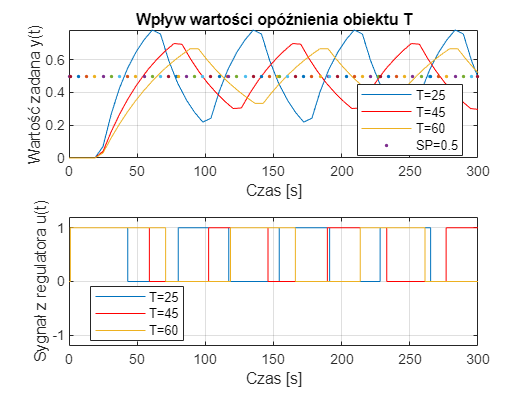

T = 25;
out1 = sim('sim_link.slx');
y1 = out1.y;
u1 = out1.u;

T = 45;
out2 = sim('sim_link.slx');
y2 = out2.y;
u2 = out2.u;

T = 60;
out3 = sim('sim_link.slx');
y3 = out3.y;
u3 = out3.u;

figure
subplot(2,1,1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, '.')
title("Wpływ wartości opóźnienia obiektu T")
legend("T=25", "T=45", "T=60", "SP=0.5", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")

subplot(2,1,2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("T=25", "T=45", "T=60", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Sygnał z regulatora u(t)")
axis([0,300,-1.2,1.2])

T=45;

Analiza wpływu wartości zadanej SP:

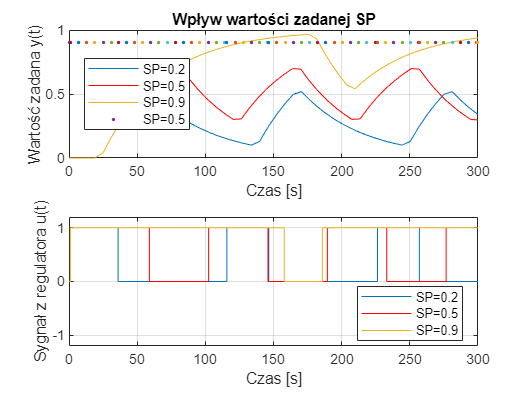

SP = 0.2;
out1 = sim('sim_link.slx');
y1 = out1.y;
u1 = out1.u;

SP = 0.5;
out2 = sim('sim_link.slx');
y2 = out2.y;
u2 = out2.u;

SP = 0.9;
out3 = sim('sim_link.slx');
y3 = out3.y;
u3 = out3.u;

figure
subplot(2,1,1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, '.')
title("Wpływ wartości zadanej SP")
legend("SP=0.2", "SP=0.5", "SP=0.9", "SP=0.5", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")

subplot(2,1,2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("SP=0.2", "SP=0.5", "SP=0.9", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Sygnał z regulatora u(t)")
axis([0,300,-1.2,1.2])

SP = 0.5;

**Obiekt Astatyczny**

Analiza wpływu wartości zadanej SP:

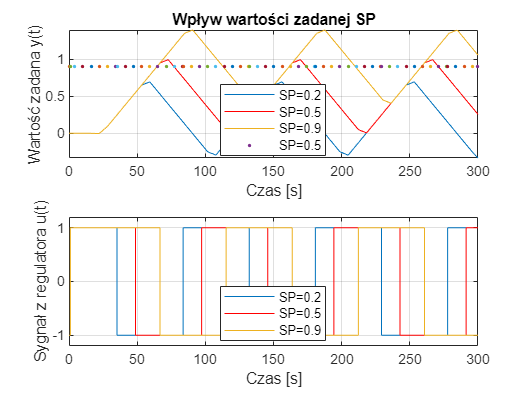

SP = 0.2;
out1 = sim('sim_link.slx');
y1 = out1.y;
u1 = out1.u;

SP = 0.5;
out2 = sim('sim_link.slx');
y2 = out2.y;
u2 = out2.u;

SP = 0.9;
out3 = sim('sim_link.slx');
y3 = out3.y;
u3 = out3.u;

figure
subplot(2,1,1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, '.')
title("Wpływ wartości zadanej SP")
legend("SP=0.2", "SP=0.5", "SP=0.9", "SP=0.5", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")

subplot(2,1,2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("SP=0.2", "SP=0.5", "SP=0.9", "Location","best")
grid on
xlabel("Czas [s]")
ylabel("Sygnał z regulatora u(t)")
axis([0,300,-1.2,1.2])